close all hidden; clear; clc;
rng(418);                                  % seed for reproducibility, 
% for this hw changing seed influences FIT drastically


### 1.a Synthetic Data 

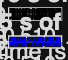

Ts   = 0.02;
N    = 3000;
t    = (0:N-1)'*Ts;


% Discrete-time plant

A    = [0.5 0.0; 
        0.0 0.2];
B    = [1; 3];
C    = [1 -0.6];
D    = 0;


% PRBS input signal in [-1,1], dwell = 10

dwell  = 10;
levels = sign(randn(ceil(N/dwell),1));     % ±1 levels
u      = repelem(levels, dwell);
u      = u(1:N); u = u(:);                 % trim, column vector


% Simulate the system

x      = zeros(2,N);
for k = 1:N-1
    x(:,k+1) = A*x(:,k) + B*u(k);
end
y0     = (C*x).' + D*u;                    % noise free output
sigma  = 0.03;                             
y      = y0 + sigma*randn(N,1);            % noisy output


% Split into estimation and validation datasets

N_est  = round(15/Ts);                     % first 15 s for estimation
u_est  = u(1:N_est);   y_est  = y(1:N_est);   y0_est = y0(1:N_est);
u_val  = u(N_est+1:end); y_val  = y(N_est+1:end); y0_val = y0(N_est+1:end);
t_est  = t(1:N_est);   t_val  = t(N_est+1:end);


% Plot the first 15 seconds

figure; 
subplot(2,1,1); plot(t_est,u_est,'k'); grid on; xlabel('time [s]'); ylabel('u');
title('First 15 s of input');
subplot(2,1,2); plot(t_est,y_est,'b'); grid on; xlabel('time [s]'); ylabel('y');
title('First 15 s of output');

### 1.b Input suitability 

% i=j=30: check full row rank of Uf and [Up;Uf].
% The input must be exciting (PE) for correct system identification.
% PRBS is theoretically PE, but it may not excite all frequencies equally well.
% A multisine input would provide stronger broadband excitation (tried for input, got %66 FIT).

i = 30; j = 30;
Ns = N_est - i - j + 1;                    
assert(Ns>0,'Ns<=0; increase N_est or reduce i/j.');


% Hankel matrices for input/output blocks

Up = zeros(i,Ns);  Uf = zeros(j,Ns);  Yf = zeros(j,Ns);
for r = 1:i, Up(r,:) = u_est(r       : r+Ns-1).'; end   % past input
for r = 1:j, Uf(r,:) = u_est(i+r     : i+r+Ns-1).'; end % future input
for r = 1:j, Yf(r,:) = y_est(i+r     : i+r+Ns-1).'; end % future output


% Rank checks

thr = @(s1,s) 1e-8*max(s1,1);                          
sUf = svd(Uf,'econ');         rankUf = sum(sUf > thr(sUf(1),sUf));
sW  = svd([Up;Uf],'econ');    rankW  = sum(sW  > thr(sW(1),sW));
fprintf('\nPE check: rank(Uf)=%d (target j=%d) | rank([Up;Uf])=%d (target i+j=%d)\n',...
        rankUf, j, rankW, i+j);


PE check: rank(Uf)=30 (target j=30) | rank([Up;Uf])=60 (target i+j=60)



% Note:
% PRBS fails to sufficiently excite certain frequency bands (%33 FIT),
% rank(Uf) or rank([Up;Uf]) may drop below the target.
% In such cases, a multisine input (superposition of sine waves) 
% can provide better excitation.


### 1.c Hankel blocks

% Pre-computed at 1.b
% Up (i×Ns): past inputs
% Uf (j×Ns): future inputs
% Yf (j×Ns): future outputs
% Ns = N_est - i - j + 1 → number of shifted data windows.


### 1.d Input Projection

W        = [Up;Uf];                         
[Qw,~]   = qr(W.',0);                        % thin QR of W^T
P        = eye(Ns) - Qw*Qw.';                % orthogonal complement projector
Yfp      = Yf * P;                           % input-projected output


### 1.e SVD of Yf*P 

[Uyy,Syy,~] = svd(Yfp,'econ');  
sv       = diag(Syy);
n        = 2;                                % known true order (A is 2×2)
fprintf('SVD: chosen order n=%d', n, n);

SVD: chosen order n=2SVD: chosen order n=2

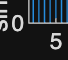

figure; stem(1:min(30,numel(sv)), sv(1:min(30,numel(sv))),'filled');
grid on; xlabel('index'); ylabel('singular value');
title('Singular values of projected Y_f');


% Two dominant singular values appear, meaning the system is second-order.
% The remaining small values correspond to noise and unmodeled effects.


### 1.f Extended Observability and State Sequence

Un   = Uyy(:,1:n);  
Sn   = Syy(1:n,1:n);
Ohat = Un * sqrt(Sn);                       % extended observability matrix

[~,~,Vn] = svd(Yfp,'econ');                 
Vn   = Vn(:,1:n);
Xhat = sqrt(Sn) * Vn.';                     % estimated state sequence


### 1.g Estimated C^ and A^ 

p      = size(C,1);                         % number of outputs
Chat   = Ohat(1:p,:);                       % first block row C^
Otop   = Ohat(1:end-p,:);                   
Obot   = Ohat(p+1:end,:);                   
Ahat   = Otop \ Obot;                       % least squares A^
fprintf('eig(Ahat) = %s\n', mat2str(eig(Ahat).',4));

eig(Ahat) = [0.6628+0.7285i 0.6628-0.7285i]


### 1.h State Propagation and Averaging

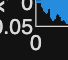

% For each column l of Yf, the estimated state at time t_l = i+l is Xhat(:,l).
% Each future prediction is propagated by Ahat, and all overlapping estimates 
% are averaged for smoother state trajectories.


nA    = n;                                   
x_sum = zeros(nA, N_est);    % accumulated state estimates per time index
x_cnt = zeros(1,  N_est);    % number of estimates contributing to each time index


% Precompute A^d

Apow = cell(j,1); 
Apow{1} = eye(nA);
for d = 2:j
    Apow{d} = Apow{d-1} * Ahat;             
end


% Sliding window accumulation

for l = 1:Ns
    tl  = i + l;                              
    x0l = Xhat(:,l);                          
    for d = 0:(j-1)
        k = tl + d;                          
        if k <= N_est
            x_sum(:,k) = x_sum(:,k) + Apow{d+1} * x0l;  
            x_cnt(k)   = x_cnt(k) + 1;                   
        end
    end
end

x_cnt(x_cnt==0) = 1;                          
xbar = x_sum ./ x_cnt;                        % avg.


% Plot

figure;
subplot(2,1,1); 
plot(t_est, xbar(1,1:N_est), 'LineWidth', 1.1); 
grid on; ylabel('x_1'); 
title('Estimated states (first 15 s)');
subplot(2,1,2); 
plot(t_est, xbar(2,1:N_est), 'LineWidth', 1.1); 
grid on; xlabel('time [s]'); ylabel('x_2');

### 1.i Estimated B^ and D^ 

nA = size(Ahat,1);
L  = max(4*nA, 30);                 % horizon length
L  = min(L, N_est-1);               % safety limit


% Precompute powers of A

Apow_t = cell(L,1); Apow_t{1} = eye(nA);
for tpow = 2:L, Apow_t{tpow} = Apow_t{tpow-1} * Ahat; end

Apow_k = cell(N_est,1); Apow_k{1} = eye(nA);
for k = 2:N_est, Apow_k{k} = Apow_k{k-1} * Ahat; end


% regression

K      = N_est - L;
Phi    = zeros(K, nA + 1 + nA);    % [B(n×1) , D(1×1) , x0(n×1)]
yy     = y_est(L+1:N_est);

for k = (L+1):N_est
    rowB = zeros(1,nA);
    for tconv = 0:(L-1)
        rowB = rowB + u_est(k-1-tconv) * (Chat * Apow_t{tconv+1});
    end
    colD = u_est(k);                 % D term
    rowX0 = Chat * Apow_k{k};        % x0 term
    idx = k - L;
    Phi(idx, 1:nA)                  = rowB;
    Phi(idx, nA+1)                  = colD;
    Phi(idx, nA+2 : nA+1+nA)        = rowX0;
end

theta = Phi \ yy;                    % LS solution
Bhat  = theta(1:nA);
Dhat  = theta(nA+1);
x0hat = theta(nA+2:end);
fprintf('Bhat = %s   |   Dhat = %.4f\n', mat2str(Bhat.',4), Dhat);

Bhat = [-0.1917 0.2361]   |   Dhat = -0.3743


### 1.j FIT Evaluation (Estimation and Validation)

FIT = @(ytrue,yh) 100*(1 - norm(ytrue - yh)/norm(ytrue - mean(ytrue)));


% Estimation

x_est = zeros(nA, N_est);
x_est(:,1) = x0hat;
yhat_est   = zeros(N_est,1);
for k = 1:N_est-1
    yhat_est(k) = Chat*x_est(:,k) + Dhat*u_est(k);
    x_est(:,k+1) = Ahat*x_est(:,k) + Bhat*u_est(k);
end
yhat_est(N_est) = Chat*x_est(:,N_est) + Dhat*u_est(N_est);

fit_est_y0 = FIT(y0_est, yhat_est);
fit_est_y  = FIT(y_est,  yhat_est);
fprintf('Estimation FIT: vs y0 = %.2f%% | vs noisy y = %.2f%%\n', fit_est_y0, fit_est_y);

Estimation FIT: vs y0 = 35.15% | vs noisy y = 34.76%




% Validation

N_val = numel(y_val);
h = min(40, N_val);                          
Phi_x0 = zeros(h, nA); gamma = zeros(h,1);
for k = 1:h
    Akm1 = eye(nA);
    for p = 1:k-1, Akm1 = Akm1 * Ahat; end
    Phi_x0(k,:) = Chat * Akm1;
    s = Dhat*u_val(k);
    for tau = 0:k-2
        Aexp = eye(nA);
        for q = 1:(k-2-tau), Aexp = Aexp * Ahat; end
        s = s + (Chat * Aexp * Bhat) * u_val(tau+1);
    end
    gamma(k) = s;
end
x0_val = Phi_x0 \ (y_val(1:h) - gamma);



% Validation free run sim

xv = zeros(nA,N_val); yhat_val = zeros(N_val,1);
xv(:,1) = x0_val;
for k = 1:N_val-1
    yhat_val(k) = Chat*xv(:,k) + Dhat*u_val(k);
    xv(:,k+1)   = Ahat*xv(:,k) + Bhat*u_val(k);
end
yhat_val(N_val) = Chat*xv(:,N_val) + Dhat*u_val(N_val);

fit_val_y0 = FIT(y0_val, yhat_val);
fit_val_y  = FIT(y_val,  yhat_val);
fprintf('Validation FIT: vs y0 = %.2f%% | vs noisy y = %.2f%%\n', fit_val_y0, fit_val_y);

Validation FIT: vs y0 = 34.90% | vs noisy y = 34.79%


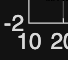


figure;
plot(t_val, y0_val,'k-', 'DisplayName','y0'); hold on;
plot(t_val, yhat_val,'b-', 'DisplayName','yhat (val)'); grid on;
legend('Location','best'); xlabel('time [s]'); ylabel('output');
title(sprintf('Validation (free run) — FIT vs y0 = %.1f%%', fit_val_y0));

### 1.k Comparison with n4sid (same estimation data)

data_est = iddata(y_est, u_est, Ts);
sys_n4   = n4sid(data_est, 2, ...
                 'Feedthrough', false, ...
                 'DisturbanceModel','none', ...
                 'Focus','simulation');

yhat_n4_est = lsim(sys_n4, u_est, t_est);
yhat_n4_val = lsim(sys_n4, u_val, t_val);

fit_n4_est  = FIT(y_est,  yhat_n4_est);
fit_n4_val  = FIT(y_val,  yhat_n4_val);
fprintf('Manual N4SID: Est %.2f%% | Val %.2f%%\nMATLAB n4sid: Est %.2f%% | Val %.2f%%\n',...
        fit_est_y, fit_val_y, fit_n4_est, fit_n4_val);

Manual N4SID: Est 34.76% | Val 34.79%
MATLAB n4sid: Est 94.04% | Val 92.99%
